# PINNs with plane stress plate (Variational Approach)

- 1 neural networks - for body force x and y both

- 4 inputs - x, y, B, H

- Random collocation points

tic
clear; close all; clc;

## 1. Definition of the network

layers = [
    featureInputLayer(4,"Normalization","none") % 4 inputs [x, y, B, H]
    fullyConnectedLayer(64)
    tanhLayer
    fullyConnectedLayer(64)
    tanhLayer
    fullyConnectedLayer(64)
    tanhLayer
    fullyConnectedLayer(4) % 4 outputs [ux_fx, uy_fx for bodyforcex & ux_fy, uy_fy for bodyforcey] pointwise
    ];

dlnet = dlnetwork(layerGraph(layers));

## 2. Parameters

E = 1;
nu = 0.3;

% BODY FORCE (kN/m^3)
fx = 1;
fy = 1;

B_min = 1;  B_max = 3;
H_min = 1;  H_max = 3;

% Collocation points for random training dataset
numInterior = 1000; % 1000 points inside domain
numBoundary = 50; % 50 points on each of the 4 boundary

% Initialize datasets (row-wise storage)
XInterior = []; %interior points
XBoundary = []; %boundary points
UBoundary = []; %boundary values

% Grid nodes
nNodesX = 32;
nNodesY = 32;
nNodes = nNodesX * nNodesY;
ndofNode = 2;
nDOF = ndofNode * nNodes;

[xGrid, yGrid] = meshgrid(linspace(0,1,nNodesX), linspace(0,1,nNodesY));
coords0 = [xGrid(:), yGrid(:)];

## 3. Data generation

numGeom = 20;

for i = 1:numGeom
    %% =====================================================
    % GEOMETRY CREATION
    % ======================================================

    B = B_min + (B_max - B_min)*rand;
    H = H_min + (H_max - H_min)*rand;

    % Normalize geometry
    Bn = 2*(B - B_min)/(B_max - B_min) - 1;
    Hn = 2*(H - H_min)/(H_max - H_min) - 1;

    %% =====================================================
    % INTERIOR COLLOCATION POINTS
    % ======================================================

    xInt = rand(numInterior,1)*B;
    yInt = rand(numInterior,1)*H;

    % Normalize to [-1,1]
    xIntN = 2*(xInt/B) - 1;
    yIntN = 2*(yInt/H) - 1;

    Xi = [xIntN, yIntN, Bn*ones(numInterior,1), Hn*ones(numInterior,1)];

    XInterior = [XInterior; Xi];

    %% =====================================================
    % BOTTOM BOUNDARY (FIXED)
    % ======================================================

    xBot = rand(numBoundary,1)*B;
    yBot = zeros(numBoundary,1);

    xBotN = 2*(xBot/B) - 1;
    yBotN = 2*(yBot/H) - 1;

    Xb = [xBotN, yBotN, Bn*ones(numBoundary,1), Hn*ones(numBoundary,1)];

    XBoundary = [XBoundary; Xb];

    % u = 0 on bottom boundary
    UBoundary = [UBoundary;zeros(numBoundary,4)];
end

disp('Geometries generation completed!');

Geometries generation completed!


disp('Data generation time:');

Data generation time:


toc

Elapsed time is 9.600500 seconds.


## 4. Training Loop

tic
numEpochs = 6000;
learnRate = 1e-3;

avgGrad = [];
avgSqGrad = [];
Wbc = 10;

% Convert ALL datasets to dlarray
dlXInt = dlarray(XInterior','CB');
dlXB   = dlarray(XBoundary','CB');
dlUB   = dlarray(UBoundary','CB');

for epoch = 1:numEpochs

    % [loss, loss_e_x, loss_e_y, loss_bc, gradients] = dlfeval(@pinnLoss, ...
    %     dlnet, dlXInt, dlXB, dlUB, dlXtr, E, nu, fx, fy, B_min, B_max, H_min, H_max);    
    [loss, loss_e_x, loss_e_y, loss_bc, gradients] = dlfeval(@pinnLoss, ...
        dlnet, dlXInt, dlXB, dlUB, E, nu, fx, fy, B_min, B_max, H_min, H_max);
    [dlnet, avgGrad, avgSqGrad] = adamupdate(dlnet, gradients, avgGrad, avgSqGrad, epoch, learnRate);

    if mod(epoch,500)==0
        % fprintf("Epoch %d | Loss %.6f | Ex %.6f | Ey %.6f | BC %.6f\n", epoch, ...
        %     extractdata(loss), extractdata(loss_e_x), extractdata(loss_e_y), extractdata(loss_bc));
        fprintf("Epoch %d | Loss %.6f | Ex %.6f | Ey %.6f | BCraw %.6f | BCweighted %.6f\n", ...
            epoch, extractdata(loss), extractdata(loss_e_x), extractdata(loss_e_y), ...
            extractdata(loss_bc), extractdata(Wbc*loss_bc));
    end

    if epoch > 5000
    learnRate = 1e-4;
    end
end

Epoch 500 | Loss -17.377192 | Ex -14.968939 | Ey -3.320156 | BCraw 0.009119 | BCweighted 0.091190
Epoch 1000 | Loss -19.835503 | Ex -17.482262 | Ey -3.382766 | BCraw 0.010295 | BCweighted 0.102953
Epoch 1500 | Loss -20.579269 | Ex -18.540459 | Ey -3.444754 | BCraw 0.014059 | BCweighted 0.140594
Epoch 2000 | Loss -21.013842 | Ex -19.126942 | Ey -3.465234 | BCraw 0.015783 | BCweighted 0.157833
Epoch 2500 | Loss -21.463770 | Ex -19.139273 | Ey -3.419013 | BCraw 0.010945 | BCweighted 0.109452
Epoch 3000 | Loss -21.751663 | Ex -19.440235 | Ey -3.429171 | BCraw 0.011177 | BCweighted 0.111774
Epoch 3500 | Loss -22.000177 | Ex -19.729670 | Ey -3.442752 | BCraw 0.011722 | BCweighted 0.117224
Epoch 4000 | Loss -22.205311 | Ex -20.128172 | Ey -3.468119 | BCraw 0.013910 | BCweighted 0.139098
Epoch 4500 | Loss -21.641268 | Ex -21.161636 | Ey -3.575132 | BCraw 0.030955 | BCweighted 0.309550
Epoch 5000 | Loss -22.762056 | Ex -20.553070 | Ey -3.476511 | BCraw 0.012675 | BCweighted 0.126752
Epoch 5500 


disp("✅ PINN training completed");

✅ PINN training completed


disp('Training time:')

Training time:


toc

Elapsed time is 4702.680663 seconds.


Ubc_check = predict(dlnet, dlXB);
maxBottomDisp = max(abs(extractdata(Ubc_check)), [], "all");
Umax_check = predict(dlnet, dlXInt);
maxTotalDisp = max(abs(extractdata(Umax_check)), [], "all");
relBottomDisp = maxBottomDisp / maxTotalDisp;

fprintf("Max bottom displacement = %.3e\n", maxBottomDisp);

Max bottom displacement = 9.973e-01


fprintf("Max total displacement  = %.3e\n", maxTotalDisp);

Max total displacement  = 4.659e+01


fprintf("Relative bottom violation = %.3e\n", relBottomDisp);

Relative bottom violation = 2.140e-02


## 5. Inference

tic
% Test geometry
Btest = 1.25;
Htest = 2;

fx_test = 2;
fy_test = 3;

bodyforcetestx = [fx_test;0];
bodyforcetesty = [0;fy_test];

coords = [coords0(:,1)*Btest, coords0(:,2)*Htest];

% Normalize spatial coordinates
xtestN = 2*(coords(:,1)'./Btest) - 1;
ytestN = 2*(coords(:,2)'./Htest) - 1;

% Normalize geometry inputs
BtestN = 2*(Btest - B_min)/(B_max - B_min) - 1;
HtestN = 2*(Htest - H_min)/(H_max - H_min) - 1;

BtestN_vec = BtestN * ones(size(xtestN));
HtestN_vec = HtestN * ones(size(ytestN));

% 4-input PINN input: [xN; yN; BN; HN]
Xtest_nodes = dlarray(single([xtestN; ytestN; BtestN_vec; HtestN_vec]), "CB");


% ============================================
% PINN SOLUTION - DISPLACEMENT
% ============================================
U_pred = forward(dlnet, Xtest_nodes);
% U_pred = predictConstrained(dlnet, Xtest_nodes);

ux_fx = U_pred(1,:);
uy_fx = U_pred(2,:);

ux_fy = U_pred(3,:);
uy_fy = U_pred(4,:);

ux_total = fx_test*ux_fx + fy_test*ux_fy;
uy_total = fx_test*uy_fx + fy_test*uy_fy;

u_x_PINN = extractdata(ux_total)';
u_y_PINN = extractdata(uy_total)';

UxN = reshape(u_x_PINN, nNodesY, nNodesX);
UyN = reshape(u_y_PINN, nNodesY, nNodesX);

disp('Inference time:')

Inference time:


toc

Elapsed time is 1.161670 seconds.



% ============================================
% FEM SOLUTION
% ============================================

[K1, F1] = buildPlaneStressFEM(coords, nNodesX, nNodesY, E, nu, bodyforcetestx);
[K2, F2] = buildPlaneStressFEM(coords, nNodesX, nNodesY, E, nu, bodyforcetesty);

% apply base fixed BC (y==0)
tol = 1e-6;
baseNodes = find(abs(coords(:,2)) < tol);
fixedDOFs = reshape([(baseNodes-1)'*ndofNode + 1; (baseNodes-1)'*ndofNode + 2], [], 1);
allDOFs = (1:nDOF)';
freeDOFs = setdiff(allDOFs, fixedDOFs);

u_fem1 = zeros(nDOF,1);
u_fem2 = zeros(nDOF,1);

u_fem1(freeDOFs) = K1(freeDOFs, freeDOFs) \ F1(freeDOFs);
u_fem2(freeDOFs) = K2(freeDOFs, freeDOFs) \ F2(freeDOFs);

u_FEM1 = u_fem1(:);
u_FEM2 = u_fem2(:);

% extract u_x and u_y components
u_x_FEM1 = u_FEM1(1:2:end);
u_y_FEM1 = u_FEM1(2:2:end);

u_x_FEM2 = u_FEM2(1:2:end);
u_y_FEM2 = u_FEM2(2:2:end);

% reshape on grid
Xcoords = reshape(coords(:,1), nNodesY, nNodesX);
Ycoords = reshape(coords(:,2), nNodesY, nNodesX);

UxF1 = reshape(u_x_FEM1, nNodesY, nNodesX);
UyF1 = reshape(u_y_FEM1, nNodesY, nNodesX);

UxF2 = reshape(u_x_FEM2, nNodesY, nNodesX);
UyF2 = reshape(u_y_FEM2, nNodesY, nNodesX);

UxF = UxF1 + UxF2;
UyF = UyF1 + UyF2;

% ============================================
% COMBINED DISPLACEMENT ERROR METRICS
% ============================================

% Assemble FEM and PINN displacement vectors in DOF order: [ux1; uy1; ux2; uy2; ...]
u_FEM = zeros(nDOF,1);
u_PINN = zeros(nDOF,1);

u_FEM(1:2:end) = UxF(:);
u_FEM(2:2:end) = UyF(:);

u_PINN(1:2:end) = UxN(:);
u_PINN(2:2:end) = UyN(:);

% Error vector
err_vec = u_FEM - u_PINN;

% Error measures
RMSE = norm(err_vec) / sqrt(numel(err_vec));
relL2 = norm(err_vec, 2) / norm(u_FEM, 2);
relLinf = norm(err_vec, Inf) / norm(u_FEM, Inf);

fprintf('\nCombined displacement errors:\n');


Combined displacement errors:


fprintf('RMSE                     = %.3e\n', RMSE);

RMSE                     = 4.802e-01


fprintf('Relative L2 error        = %.3e\n', relL2);

Relative L2 error        = 2.692e-02


fprintf('Relative infinity error  = %.3e\n', relLinf);

Relative infinity error  = 3.260e-02



% RELATIVE L2 ERRORS FOR BOTH DISPLACEMENTS SEPARARELY

relErrUx = norm(UxF(:)-UxN(:)) / norm(UxF(:));
relErrUy = norm(UyF(:)-UyN(:)) / norm(UyF(:));

fprintf('Relative L2 Error ux = %.3e\n', relErrUx);

Relative L2 Error ux = 2.042e-02


fprintf('Relative L2 Error uy = %.3e\n', relErrUy);

Relative L2 Error uy = 6.299e-02


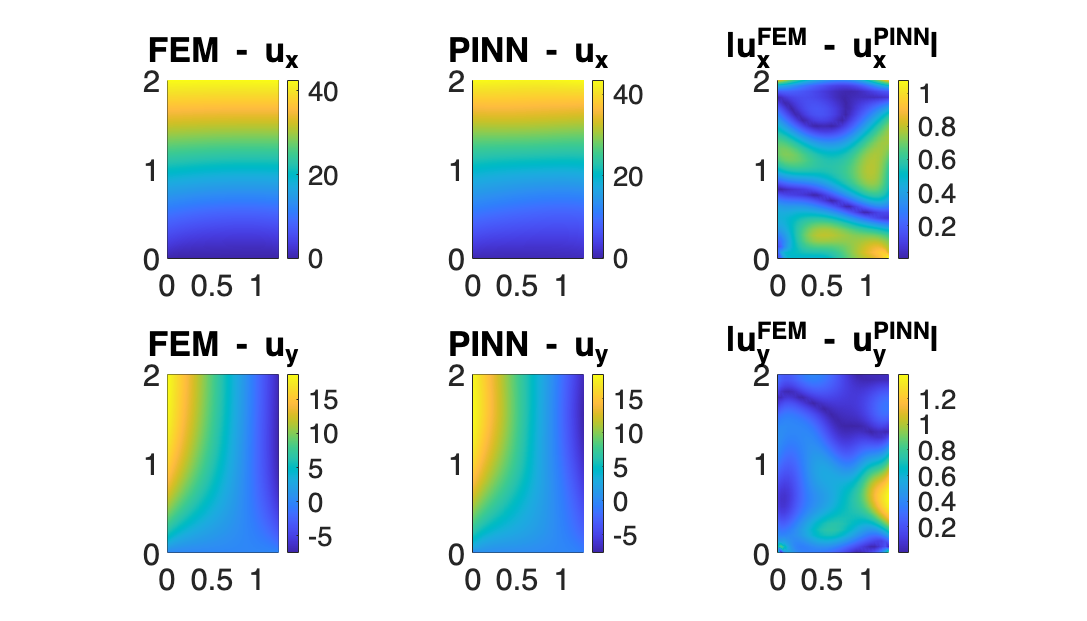


% ============================================
% ABSOLUTE ERROR
% ============================================

Err_u = abs(UxF - UxN);
Err_v = abs(UyF - UyN);

% Coordinates reshaped
Xcoords = reshape(coords(:,1), nNodesY, nNodesX);
Ycoords = reshape(coords(:,2), nNodesY, nNodesX);

% ============================================
% PLOTS
% ============================================

figure('Position',[100 100 1400 800]);

subplot(2,3,1);
pcolor(Xcoords, Ycoords, UxF); shading interp; colorbar; axis equal tight;
title('FEM - u_x');

subplot(2,3,2);
pcolor(Xcoords, Ycoords, UxN); shading interp; colorbar; axis equal tight;
title('PINN - u_x');

subplot(2,3,3);
pcolor(Xcoords, Ycoords, Err_u); shading interp; colorbar; axis equal tight;
title('|u_x^{FEM} - u_x^{PINN}|');

subplot(2,3,4);
pcolor(Xcoords, Ycoords, UyF); shading interp; colorbar; axis equal tight;
title('FEM - u_y');

subplot(2,3,5);
pcolor(Xcoords, Ycoords, UyN); shading interp; colorbar; axis equal tight;
title('PINN - u_y');

subplot(2,3,6);
pcolor(Xcoords, Ycoords, Err_v); shading interp; colorbar; axis equal tight;
title('|u_y^{FEM} - u_y^{PINN}|');

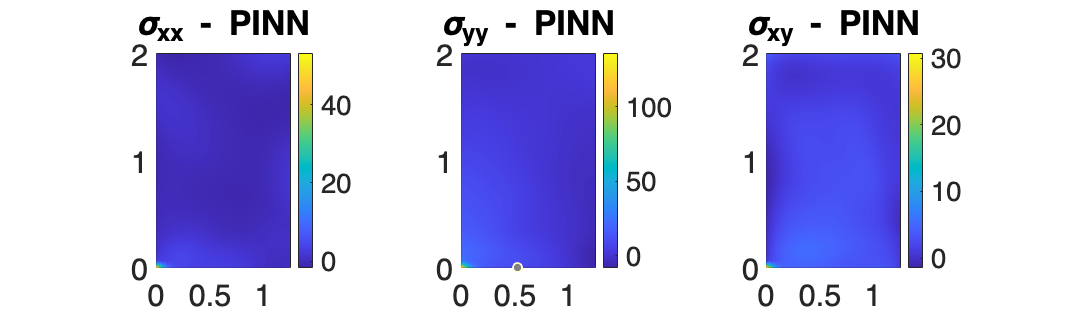


% ============================================
% PINN STRESSES
% ============================================

[sxx_fx, syy_fx, sxy_fx] = dlfeval(@computeStressCase, ...
    dlnet, Xtest_nodes, E, nu, B_min, B_max, H_min, H_max, 1);

[sxx_fy, syy_fy, sxy_fy] = dlfeval(@computeStressCase, ...
    dlnet, Xtest_nodes, E, nu, B_min, B_max, H_min, H_max, 2);

sxx_pred = fx_test*sxx_fx + fy_test*sxx_fy;
syy_pred = fx_test*syy_fx + fy_test*syy_fy;
sxy_pred = fx_test*sxy_fx + fy_test*sxy_fy;

SxxN = reshape(extractdata(sxx_pred)', nNodesY, nNodesX);
SyyN = reshape(extractdata(syy_pred)', nNodesY, nNodesX);
SxyN = reshape(extractdata(sxy_pred)', nNodesY, nNodesX);

figure('Position',[100 100 1400 400]);

subplot(1,3,1);
pcolor(Xcoords, Ycoords, SxxN);
shading interp; colorbar; axis equal tight;
title('\sigma_{xx} - PINN');

subplot(1,3,2);
pcolor(Xcoords, Ycoords, SyyN);
shading interp; colorbar; axis equal tight;
title('\sigma_{yy} - PINN');

subplot(1,3,3);
pcolor(Xcoords, Ycoords, SxyN);
shading interp; colorbar; axis equal tight;
title('\sigma_{xy} - PINN');


disp('Inference time:')

Inference time:


toc

Elapsed time is 8.653674 seconds.


## Functions

  function [loss, loss_e_x, loss_e_y, loss_bc, gradients] = pinnLoss( ...
    dlnet, X, Xbc, UBoundary, E, nu, fx, fy, B_min, B_max, H_min, H_max)

    Bn = X(3,:);
    Hn = X(4,:);

    B = (Bn + 1)/2 * (B_max - B_min) + B_min;
    H = (Hn + 1)/2 * (H_max - H_min) + H_min;

    % ============================================================
    % 1️⃣ Forward Pass
    % ============================================================
    U = forward(dlnet, X);
    % ux = U(1,:);
    % uy = U(2,:);

    ux_fx = U(1,:);   % displacement ux due to fx = 1, fy = 0
    uy_fx = U(2,:);   % displacement uy due to fx = 1, fy = 0

    ux_fy = U(3,:);   % displacement ux due to fx = 0, fy = 1
    uy_fy = U(4,:);   % displacement uy due to fx = 0, fy = 1


    % ============================================================
    % 2️⃣ Derivatives (chain rule scaling)
    % ============================================================
    gradUx_fx = dlgradient(sum(ux_fx), X,'EnableHigherDerivatives', true);
    gradUy_fx = dlgradient(sum(uy_fx), X,'EnableHigherDerivatives', true);

    gradUx_fy = dlgradient(sum(ux_fy), X,'EnableHigherDerivatives', true);
    gradUy_fy = dlgradient(sum(uy_fy), X,'EnableHigherDerivatives', true);

    dux_dx_fx = gradUx_fx(1,:) .* (2 ./ B);
    dux_dy_fx = gradUx_fx(2,:) .* (2 ./ H);
    duy_dx_fx = gradUy_fx(1,:) .* (2 ./ B);
    duy_dy_fx = gradUy_fx(2,:) .* (2 ./ H);

    dux_dx_fy = gradUx_fy(1,:) .* (2 ./ B);
    dux_dy_fy = gradUx_fy(2,:) .* (2 ./ H);
    duy_dx_fy = gradUy_fy(1,:) .* (2 ./ B);
    duy_dy_fy = gradUy_fy(2,:) .* (2 ./ H);


    % ============================================================
    % 3️⃣ Strain
    % ============================================================
    exx_fx = dux_dx_fx;
    eyy_fx = duy_dy_fx;
    % exy = 0.5*(dux_dy + duy_dx); %tensor shear strain
    gxy_fx = dux_dy_fx + duy_dx_fx; %engineering shear strain

    exx_fy = dux_dx_fy;
    eyy_fy = duy_dy_fy;
    gxy_fy = dux_dy_fy + duy_dx_fy; %engineering shear strain
    
    % ============================================================
    % 4️⃣ Stress (plane stress)
    % ============================================================
    C = E/(1 - nu^2);
    G = E/(2*(1+nu));

    sxx_fx = C*(exx_fx + nu*eyy_fx);
    syy_fx = C*(eyy_fx + nu*exx_fx);
    % sxy = C*(1 - nu)*exy;
    sxy_fx = G .* gxy_fx;

    sxx_fy = C*(exx_fy + nu*eyy_fy);
    syy_fy = C*(eyy_fy + nu*exx_fy);
    sxy_fy = G .* gxy_fy;
    
    % ============================================================
    % 5️⃣ Potential energy density for two unit load cases
    % ============================================================
    % Case 1: unit body force in x direction: b = [1; 0]
    W_fx = 0.5*(sxx_fx.*exx_fx + syy_fx.*eyy_fx + sxy_fx.*gxy_fx) - fx * ux_fx;

    % Case 2: unit body force in y direction: b = [0; 1]
    W_fy = 0.5*(sxx_fy.*exx_fy + syy_fy.*eyy_fy + sxy_fy.*gxy_fy) - fy * uy_fy;
    
    W_fx = W_fx .* B .* H;
    W_fy = W_fy .* B .* H;

    loss_e_x = mean(W_fx, 'all');
    loss_e_y = mean(W_fy, 'all');

    % ============================================================
    % 6️⃣ BOUNDARY CONDITION (y = 0 → fixed)
    % ============================================================
    Ubc = forward(dlnet, Xbc);
    loss_bc = mean(Ubc.^2, 'all');

    % ============================================================
    % Final loss
    % ============================================================
    Wbc = 100;
    loss = loss_e_x + loss_e_y + Wbc*loss_bc;
    
    gradients = dlgradient(loss, dlnet.Learnables);
end

function [sxx, syy, sxy] = computeStressCase(dlnet, X, E, nu, B_min, B_max, H_min, H_max, caseID)

    Bn = X(3,:);
    Hn = X(4,:);

    B = (Bn + 1)/2 * (B_max - B_min) + B_min;
    H = (Hn + 1)/2 * (H_max - H_min) + H_min;

    U = forward(dlnet, X);

    if caseID == 1
        ux = U(1,:);
        uy = U(2,:);
    elseif caseID == 2
        ux = U(3,:);
        uy = U(4,:);
    else
        error('caseID must be 1 for fx case or 2 for fy case');
    end

    gradUx = dlgradient(sum(ux), X, 'EnableHigherDerivatives', true);
    gradUy = dlgradient(sum(uy), X, 'EnableHigherDerivatives', true);

    dux_dx = gradUx(1,:) .* (2 ./ B);
    dux_dy = gradUx(2,:) .* (2 ./ H);

    duy_dx = gradUy(1,:) .* (2 ./ B);
    duy_dy = gradUy(2,:) .* (2 ./ H);

    exx = dux_dx;
    eyy = duy_dy;
    gxy = dux_dy + duy_dx;

    C = E/(1 - nu^2);
    G = E/(2*(1 + nu));

    sxx = C*(exx + nu*eyy);
    syy = C*(eyy + nu*exx);
    sxy = G*gxy;
    
end

function [K,F] = buildPlaneStressFEM(coords,nx,ny,E,nu,bodyForce)
    % Structured mesh of 4-node bilinear quadrilateral elements
    nNodes = nx*ny;
    nElemX = nx-1; nElemY = ny-1;
    nElem = nElemX * nElemY;
    ndofNode = 2;
    nDOF = nNodes * ndofNode; %total dof of system

    % element connectivity matrix
    % (ix, iy) is one quadrilateral element
    conn = zeros(nElem,4);
    for ix = 1:nElemX
        for jy = 1:nElemY
            n1 = (ix-1)*ny + jy;
            n2 = ix*ny + jy;
            n3 = ix*ny + (jy+1);
            n4 = (ix-1)*ny + (jy+1);
            e = (ix-1)*nElemY + jy; %This converts the 2D element index (ix, jy) into a single element number
            conn(e,:) = [n1 n2 n3 n4]; %Element e connects nodes n1, n2, n3, n4
        end
    end

    K = zeros(nDOF);
    F = zeros(nDOF,1);

    % Plane stress constitutive matrix
    D = E / (1 - nu^2) * [1, nu, 0;
                          nu, 1, 0;
                          0, 0, (1-nu)/2];

    % 2x2 Gauss
    gp = [-1/sqrt(3), 1/sqrt(3)];
    wgp = [1,1];

    for e = 1:nElem
        nodes = conn(e,:);
        xe = coords(nodes,1);
        ye = coords(nodes,2);

        %element stiffness and force matrix
        Ke = zeros(8,8);
        Fe = zeros(8,1);

        % Reduced integration term B0 for shear (as in original)
        xi = 0; eta = 0;
        [N0, dNdxi0, dNdeta0] = shape4(xi,eta);
        J0 = [dNdxi0'; dNdeta0'] * [xe, ye];
        detJ0 = det(J0);
        invJ0 = inv(J0);
        dN0 = [dNdxi0, dNdeta0] * invJ0;

        B0 = zeros(3,8);
        for a = 1:4
            dNx = dN0(a,1);
            dNy = dN0(a,2);
            col = (a-1)*2;
            B0(1, col + 1) = dNx;
            B0(2, col + 2) = dNy;
            B0(3, col + 1) = dNy;
            B0(3, col + 2) = dNx;
        end

        for i = 1:2
            for j = 1:2
                xi = gp(i); eta = gp(j);
                [N, dNdxi, dNdeta] = shape4(xi,eta);
                J = [dNdxi'; dNdeta'] * [xe, ye];
                detJ = det(J);
                invJ = inv(J);
                dN = [dNdxi, dNdeta] * invJ;

                B = zeros(3,8);
                for a = 1:4
                    dNx = dN(a,1);
                    dNy = dN(a,2);
                    col = (a-1)*2;
                    B(1, col + 1) = dNx;
                    B(2, col + 2) = dNy;
                    B(3, col + 1) = dNy;
                    B(3, col + 2) = dNx;
                end

                % replace shear row with reduced B0 shear row
                B(3,:) = B0(3,:);

                Ke = Ke + (B' * D * B) * detJ * wgp(i) * wgp(j);

                Nmat = zeros(2,8);
                for a = 1:4
                    Nmat(1, (a-1)*2 + 1) = N(a);
                    Nmat(2, (a-1)*2 + 2) = N(a);
                end
                Fe = Fe + (Nmat' * bodyForce) * detJ * wgp(i) * wgp(j);
            end
        end

        % assemble
        gdofs = zeros(8,1);
        for a = 1:4
            node = nodes(a);
            gdofs((a-1)*2 + (1:2)) = (node-1)*2 + (1:2);
        end
        K(gdofs, gdofs) = K(gdofs, gdofs) + Ke;
        F(gdofs) = F(gdofs) + Fe;
    end
end

function [N, dNdxi, dNdeta] = shape4(xi,eta)
    N = 0.25*[(1-xi)*(1-eta);
              (1+xi)*(1-eta);
              (1+xi)*(1+eta);
              (1-xi)*(1+eta)];
    dNdxi  = 0.25*[-(1-eta); (1-eta); (1+eta); -(1+eta)];
    dNdeta = 0.25*[-(1-xi); -(1+xi); (1+xi);  (1-xi)];
end